# Create difference of two rectangles

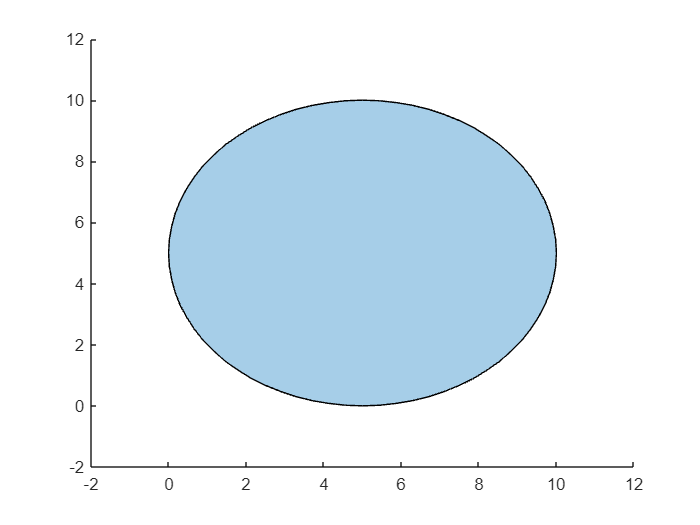

clear all;
close all;
clear plot;
clc
centre = [5, 5];
radius = 5;

% Number of points to generate
num_points = 73;

% Generate points on the circumference of the circle
angles = linspace(0, 2*pi, num_points);
cir_pts_x = centre(1) + radius * cos(angles);
cir_pts_y = centre(2) + radius * sin(angles);

% Round coordinates to a certain precision (e.g., 6 decimal places)
precision = 2;
cir_pts_x_rounded = round(cir_pts_x, precision);
cir_pts_y_rounded = round(cir_pts_y, precision);

% Combine rounded x and y coordinates
cir_pts_rounded = [cir_pts_x_rounded', cir_pts_y_rounded'];

% Create polyshape object
poly_circle = polyshape(cir_pts_rounded);
figure(1)
plot(poly_circle);

rect1 = [0, 0; 0, 5; 10, 5; 10, 0]; % Vertices of rectangle 1
rect2 = [5, 1; 5, 4; 14, 4; 14, 1]; % Vertices of rectangle 2

% Create polyshapes from the rectangles
poly1 = polyshape(rect1);
poly2 = polyshape(rect2);
% Find the difference between the two polyshapes
differencePoly1 = subtract(poly1,poly_circle);
differencePoly2 = subtract(poly_circle,poly1);
% Get the vertices of the resulting polygon
differenceVertices = differencePoly1.Vertices;
% Display the difference vertices
disp('Difference vertices:');

Difference vertices:


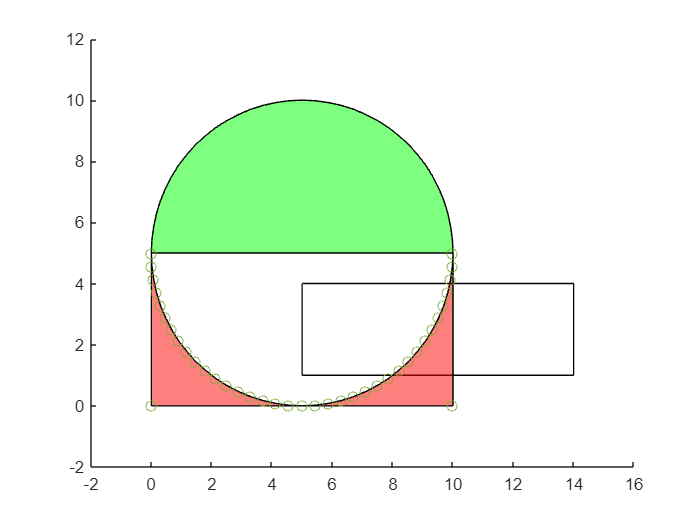

% Plot the rectangles and their difference
figure;
plot(poly1, 'FaceColor', 'white', 'FaceAlpha', 0.5);
hold on;
plot(poly2, 'FaceColor', 'white', 'FaceAlpha', 0.5);
plot(differencePoly1, 'FaceColor', 'red', 'FaceAlpha', 0.5);
plot(differencePoly2, 'FaceColor', 'green', 'FaceAlpha', 0.5);
scatter(differenceVertices(:,1),differenceVertices(:,2));